t = linspace(-2, 2, 100)

t =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202




sig = arrayfun(@rect, t);
plot(t, sig)
hold on 

N = 48

N = 48

windowSize = N; 
b = (1/windowSize)*ones(1,windowSize);
% y = filter(b, 1, sig);
y = conv(sig, b, "same")

y =          0    0.0208    0.0417    0.0625    0.0833    0.1042    0.1250    0.1458    0.1667    0.1875    0.2083    0.2292    0.2500    0.2708    0.2917    0.3125    0.3333    0.3542    0.3750    0.3958    0.4167    0.4375    0.4583    0.4792    0.5000    0.5208    0.5417    0.5625    0.5833    0.6042    0.6250    0.6458    0.6667    0.6875    0.7083    0.7292    0.7500    0.7708    0.7917    0.8125    0.8333    0.8542    0.8750    0.8958    0.9167    0.9375    0.9583    0.9792    1.0000    1.0000


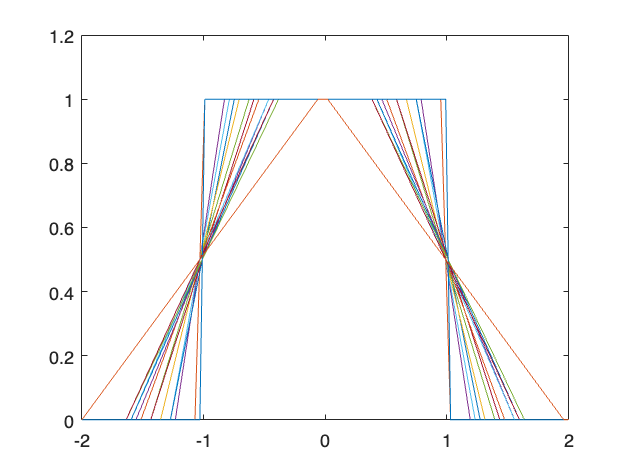

plot(t, y)

function y = rect(x)
if abs(x) < 1
    y=1;
else
    y=0;
end
end